Signal to be Transmitted

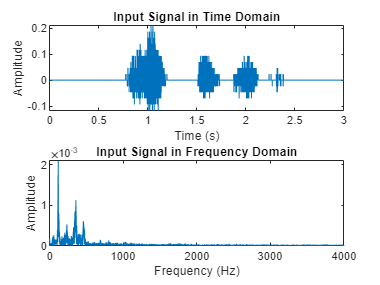

%Signal Generator

%fs = 8000;
%fc = 600; %Carrier frequency !! Limit fc<800 to avoid freqdomain aliasing 
%nbits = 8; % 8 bits is enough;  
%audioduration = 3;
%ini_phase = 0; % Phase initial


%signal0 = audiorecorder(fs,nbits,1,0);% device id is zero (Default Mic)
%recordblocking(signal0,audioduration);
%speech_data = getaudiodata(signal0,'int16') % save as a int16 array
%input_signal_location = 'C:\Users\Xavier\Desktop\LBYEC4A\inputaudio.wav' 
%audiowrite(input_signal_location,speech_data,fs)

input_audio = audioread('inputaudio.wav');

[inputaudio, Fs] = audioread('inputaudio.wav');
inputaudio = 3*inputaudio; % Amplify Signal

st = length(inputaudio);
time = st/Fs;
t = (0:1/Fs:time-1/Fs); %Time Domain
[Nf,P] = size(inputaudio);                 
f = (-Fs/2:Fs/(Nf-1):Fs/2);   
inputaudiofft = fftshift(fft(inputaudio)); %Frequency Domain

figure(1) 
subplot(211);
plot(t,inputaudio); %Time Domain
xlabel('Time (s)');
ylabel('Amplitude');
title('Input Signal in Time Domain');

subplot(212);
plot(frequencyAxis,abs(frequencySpectrum)); %Frequency Domain
xlabel ('Frequency (Hz)'); ylabel('Amplitude'); xlim([0 max(frequencyAxis)]);
title('Input Signal in Frequency Domain');

Encode the Analog Signal to Discrete Signal

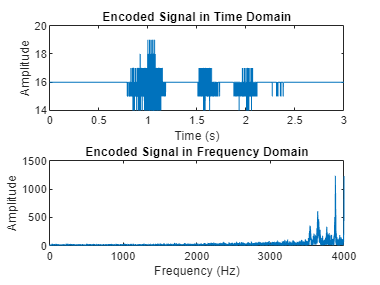

N = 5;
M = 2^N;
yy = uencode(inputaudio,N);

figure(2)
subplot(211);
plot(t,yy); %Time Domain
xlabel('Time (s)');
ylabel('Amplitude');
title('Encoded Signal in Time Domain');

modfft = fft(yy);
subplot(212);
plot(f,abs(modfft)); %Frequency Domain
xlabel ('Frequency (Hz)'); ylabel('Amplitude'); xlim([0 max(f)]);
title('Encoded Signal in Frequency Domain');

Modulate the Signal using QAM 32

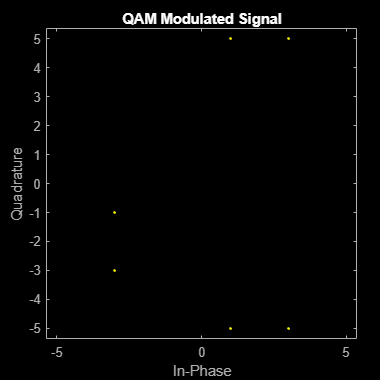

modulatedsig = qammod(yy,M);
figure(3)
scatterplot(modulatedsig);title('QAM Modulated Signal');

Create a Filter to limit the signal to the desired frequency band

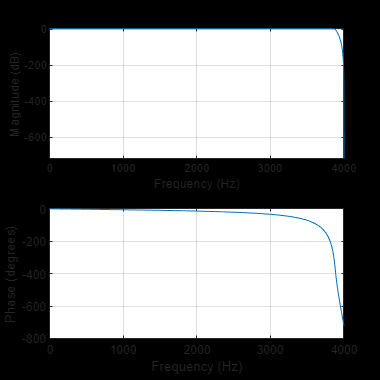

fs = 8000;
Fn = fs/2;
Wp = 3900/Fn;                                               
Ws = 3000/Fn;                                               
Rp =   1;                                                   
Rs = 150;                                                   
[n,Wn] = buttord(Wp,Ws,Rp,Rs);                              
[z,p,k] = butter(n,Wn);                                     % Butterworth filter
[sosb,gb] = zp2sos(z,p,k); 
freqz(sosb, 2^20, Fs)                                       % Filter Bode Plot

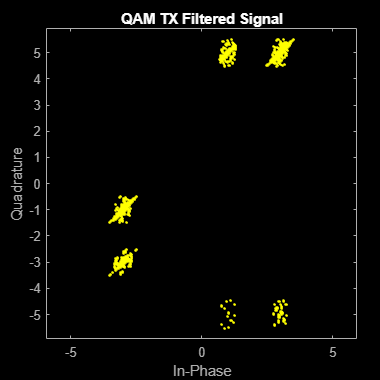

tx_filteredsig = filtfilt(sosb, gb, modulatedsig);

% tx_filteredsig = filter(filter_coefficients, 1, modulatedsig)
scatterplot(tx_filteredsig);title('QAM TX Filtered Signal');

Amplify the Signal for better transmission

tx_filteredsig = 10*tx_filteredsig

tx_filteredsig =   30.0000 +50.0000i
  30.0000 +50.0000i
  30.0000 +50.0000i
  30.0000 +50.0000i
  30.0000 +50.0000i
  30.0000 +50.0000i
  30.0000 +50.0000i
  30.0000 +50.0000i
  30.0000 +50.0000i
  30.0000 +50.0000i


Add Noise (show constellation diagram with different S/N)

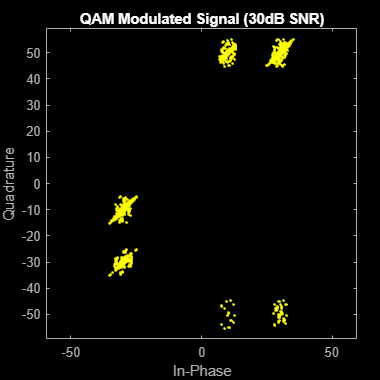

SNR1 = 30; %30 SNR
snr30 = awgn(tx_filteredsig, SNR1);
figure(4)
scatterplot(snr30);title('QAM Modulated Signal (30dB SNR)');

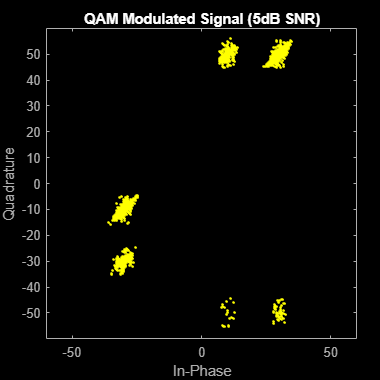


SNR2 = 5; %5 SNR
snr5 = awgn(tx_filteredsig, SNR2);
figure(5)
scatterplot(snr5);title('QAM Modulated Signal (5dB SNR)');

Filter the noisy signal 

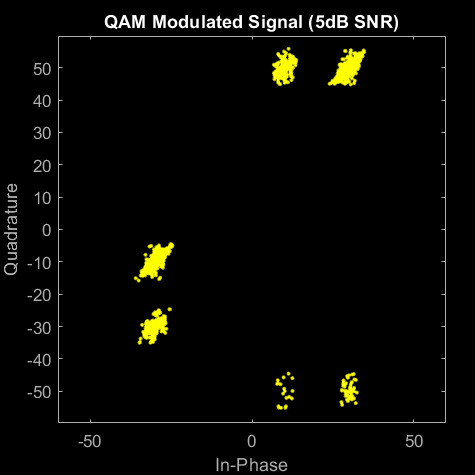

rx_filteredsignal5 = filter(Wn,n,snr5);
scatterplot(snr5);title('QAM Modulated Signal (5dB SNR)');


rx_filteredsignal30 =filter(Wn,n,snr30);
scatterplot(snr30);title('QAM Modulated Signal (30dB SNR)');

rx_filteredsignal5 = rx_filteredsignal5*3;

rx_filteredsignal30 = rx_filteredsignal30*3

rx_filteredsignal30 =   10.8925 +18.1868i
  10.9068 +18.1833i
  10.9119 +18.1771i
  10.9028 +18.1793i
  10.8913 +18.1762i
  10.9163 +18.1787i
  10.9091 +18.1800i
  10.9109 +18.1736i
  10.9131 +18.1845i
  10.9037 +18.1725i


Demodulate the Signal

Demodulatedsnr30 = qamdemod(rx_filteredsignal30,M); %30 SNR demod
Demodulatedsnr5 = qamdemod(rx_filteredsignal5,M); %5 SNR demod

Compute the Bit Error Rate (BER)

[S1, R1] = biterr(Demodulatedsnr30, yy) %30 SNR BER

S1 = 5234

R1 = 0.0436

[S2, R2] = biterr(Demodulatedsnr5, yy) %5 SNR BER

S2 = 5238

R2 = 0.0437

Recover the Received Signal 

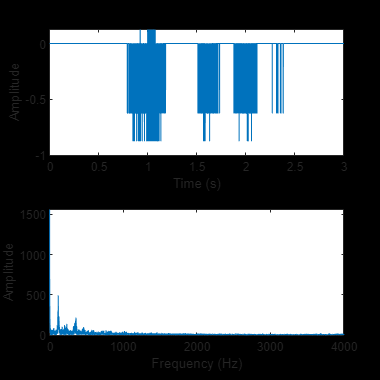

Recoveredsnr30 = udecode(uint32(Demodulatedsnr30),N);
Recoveredsnr5 = udecode(uint32(Demodulatedsnr5),N);

% sound(Recoveredsnr30,Fs)
% audiowrite('Digital_30SNR.wav',Recoveredsnr30,Fs);
% sound(Recoveredsnr5,Fs)
% audiowrite('Digital_5SNR.wav',Recoveredsnr5,Fs);

figure(6)
subplot(211);
plot(t,Recoveredsnr30); %Time Domain
title('Recovered Signal (30dB SNR) in Time Domain');
xlabel('Time (s)');ylabel('Amplitude');

highdbFFT = fftshift(fft(Recoveredsnr30));
subplot(212);
plot(f,abs(highdbFFT)); %Frequency Domain
xlabel ('Frequency (Hz)');ylabel('Amplitude'); xlim([0 max(f)]); 
title('Recovered Signal (30dB SNR) in Frequency Domain');


receivedsignalfile = 'C:\Users\Xavier\Desktop\LBYEC4A\snr30.wav';
audiowrite(receivedsignalfile,Recoveredsnr30,fs);

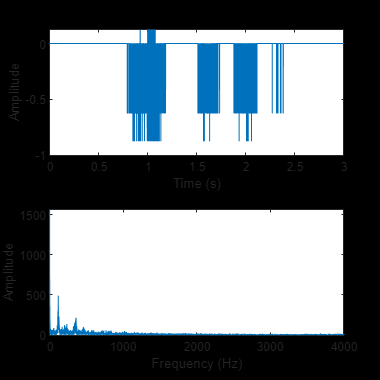

figure(7)
subplot(211);
plot(t,Recoveredsnr5); %Time Domain
xlabel('Time (s)');ylabel('Amplitude');
title('Recovered Signal (5dB SNR) in Time Domain');

lowsnrFFT = fftshift(fft(Recoveredsnr5));
subplot(212);
plot(f,abs(lowsnrFFT)); %Frequency Domain
xlabel ('Frequency (Hz)'); ylabel('Amplitude'); xlim([0 max(f)]);
title('Recovered Signal (5dB SNR) in Frequency Domainn');


receivedsignalfile = 'C:\Users\Xavier\Desktop\LBYEC4A\snr5.wav'; %Change the directory according to your pc
audiowrite(receivedsignalfile,Recoveredsnr5,fs);